Salidas del sistema en Lazo Cerrado

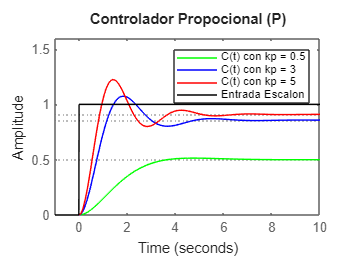

kp = 0.5;
Gc = tf(kp);
% FTTD = Función de Transferencia de la Trayectoria Directa
% Funciones de Transferencia que hay entre la Entrada
% y la Salida sin incluir la realimentación
FTTD = Gp * Gc;
FTLC1 = feedback(FTTD, H);

kp = 3;
Gc = tf(kp);
FTTD = Gp * Gc;
FTLC2 = feedback(FTTD, H);

kp = 5;
Gc = tf(kp);
FTTD = Gp * Gc;
FTLC3 = feedback(FTTD, H);

step(FTLC1, 'g', FTLC2, 'b', FTLC3, 'r');
xlim([-1 10]);
ylim([0 1.6]);

hold on;
t=(-1:0.01:10);
unistep = t >= 0;
plot(t, unistep, 'k');

title('Controlador Propocional (P)');
legend('C(t) con kp = 0.5', 'C(t) con kp = 3', 'C(t) con kp = 5', 'Entrada Escalon');